# Blue Whale Tracking - Report

This report will analyze the satellite tracks recorded from blue whales in the Northeast Pacific from 1993 - 2008 ([https://doi.org/10.5441/001/1.5ph88fk2](https://doi.org/10.5441/001/1.5ph88fk2)). The analysis will focus on seasonality of the data, meaning the relationship between the recorded locations and the time of year. Blue whales typically migrate between feeding grounds in the summer and breeding grounds in the winter. 

### Load data

First, we load the data. The `whales` dataset has already been preprocessed to remove missing data, low-quality measurements, and outliers. For details of this preprocessing, see Section 3.1 in [MATLAB Essentials](https://www.edx.org/course/matlab-essentials). 

The second loaded variable `Seasonal` is a custom colormap designed to show the seasonal behavior. This colormap was created with the [Colormap Editor](https://www.mathworks.com/help/matlab/ref/colormapeditor.html), but there are also many great tools available on the File Exchange for [customizing colormaps](https://www.mathworks.com/matlabcentral/fileexchange?q=colormaps). 

load cleanWhaleData.mat whales
load seasonalColormap.mat Seasonal

### Add day of year variable

Next, we create a variable with the day of year for each timestamp. These values will range from 1 to 365, and it will give us a rough idea of the season in which each timestamp was collected.

- **Spring** (Mar 21 to Jun 21) $\approx$ Day 81 to 172

- **Summer** (Jun 22 to Sep 22) $\approx$ Day 173 to 266

- **Autumn** (Sep 23 to Dec 20) $\approx$ Day 267 to 355 

- **Winter** (Dec 21 to Mar 20) $\approx$ Day 356 to Day 80

whales.dayOfYear = day(whales.timestamp,"dayofyear");

### Visualize seasonality with custom colormap

The day of year is cyclical, meaning `dayOfYear=1` is the day that follows `dayOfYear=365`. Therefore, we need a colormap that indicates this cyclical nature. The [`hsv`](https://www.mathworks.com/help/matlab/ref/hsv.html) colormap in MATLAB has this property, but it contains a full spectrum of colors, so it's difficult to correlate these colors with the seasons of the year.

Instead we use a custom colormap with four main colors (blue, green, yellow, and orange) to roughly represent the different seasons. 

This colormap makes it easier to observes how the values relate to the season. The relationship will be represented in a colorbar on the figure. 

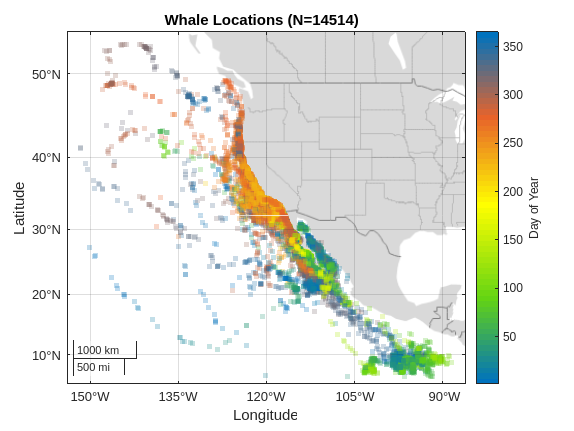

% Create the scatter plot 
geoscatter(whales.latitude,whales.longitude,16, ...
    whales.dayOfYear,"filled","s","MarkerFaceAlpha",0.25);
title("Whale Locations (N=" + height(whales) + ")  ")
geobasemap("grayland")
geolimits([5.1667 54.3183],[-153.9389 -86.1991])

% Change the colormap and add the colorbar
clim([1 365])
cb = colorbar;
cb.Label.String = "Day of Year";
cmap = colormap(Seasonal);

This figure shows that the data has a trend with the seasons. A large majority of northern data points (30°N to 50°N) were collected in the summer and autumn, whereas most of the data points in the southernmost areas (5°N to 15°N) were collected in the winter and spring. 

### Quantify the trend with summary statistics for `dayOfYear`

The last thing we'll do is calculate the mean and average `dayOfYear` values for two different latitude regions:

- Latitude > 35°N

- Latitude < 15°N

If there's a seasonal trend in the data, then the mean values in these two regions should be significantly different

northernDays = whales.dayOfYear(whales.latitude > 35);
southernDays = whales.dayOfYear(whales.latitude < 15);
meanDayOfYear = [mean(northernDays);mean(southernDays)];
results = table(meanDayOfYear,'RowNames',["Latitude > 35°N";"Latitude < 15°N"])

results = 2x1 table
                       meanDayOfYear
                       _____________

    Latitude > 35°N        268.6    
    Latitude < 15°N       105.79    


There average day of year in the northern region is 269 (around Sep 26) while the mean day of year for the southern region is 105 (around Apr 15). This is a difference of ~4 months. Hypothesis testing would be needed to determine the degree of statistical significance, but there is a clear trend where blue whales in this region tend to spend the summer/fall months much farther north than in the winter/spring months.